cd /Users/lumizhang/Documents/GitHub/AI_B_Project_2023
clc;
clear;

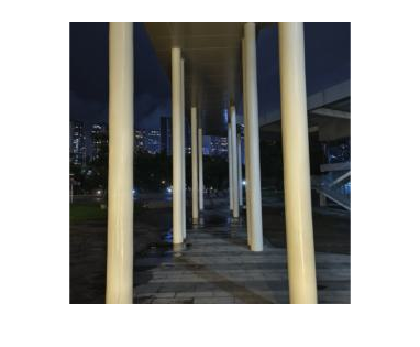

source = imread("dataset/img_256/19.jpg");
imshow(source);

-----

checking picture number 01


Chi-squared distance (RGB) is: 1.046


SSIM score is: 0.467


Hue similarity is: 0.541


-----

-----

checking picture number 02


Chi-squared distance (RGB) is: 0.844


SSIM score is: 0.419


Hue similarity is: 0.693


-----

-----

checking picture number 03


Chi-squared distance (RGB) is: 0.849


SSIM score is: 0.455


Hue similarity is: 0.298


-----

-----

checking picture number 04


Chi-squared distance (RGB) is: 0.480


SSIM score is: 0.541


Hue similarity is: 0.472


-----

-----

checking picture number 05


Chi-squared distance (RGB) is: 1.075


SSIM score is: 0.464


Hue similarity is: 0.407


-----

-----

checking picture number 06


Chi-squared distance (RGB) is: 0.972


SSIM score is: 0.442


Hue similarity is: 0.500


-----

-----

checking picture number 07


Chi-squared distance (RGB) is: 0.469


SSIM score is: 0.525


Hue similarity is: 0.483


-----

-----

checking picture number 08


Chi-squared distance (RGB) is: 0.560


SSIM score is: 0.467


Hue similarity is: 0.682


-----

-----

checking picture number 09


Chi-squared distance (RGB) is: 0.809


SSIM score is: 0.465


Hue similarity is: 0.392


-----

-----

checking picture number 10


Chi-squared distance (RGB) is: 1.164


SSIM score is: 0.509


Hue similarity is: 0.844


-----

-----

checking picture number 11


Chi-squared distance (RGB) is: 0.430


SSIM score is: 0.539


Hue similarity is: 0.427


-----

-----

checking picture number 12


Chi-squared distance (RGB) is: 0.779


SSIM score is: 0.484


Hue similarity is: 0.449


-----

-----

checking picture number 13


Chi-squared distance (RGB) is: 0.818


SSIM score is: 0.450


Hue similarity is: 0.646


-----

-----

checking picture number 14


Chi-squared distance (RGB) is: 0.945


SSIM score is: 0.464


Hue similarity is: 0.315


-----

-----

checking picture number 15


Chi-squared distance (RGB) is: 0.480


SSIM score is: 0.541


Hue similarity is: 0.472


-----

-----

checking picture number 16


Chi-squared distance (RGB) is: 1.117


SSIM score is: 0.487


Hue similarity is: 0.287


-----

-----

checking picture number 17


Chi-squared distance (RGB) is: 0.385


SSIM score is: 0.423


Hue similarity is: 0.299


-----

-----

checking picture number 18


Chi-squared distance (RGB) is: 0.755


SSIM score is: 0.420


Hue similarity is: 0.391


-----

-----

checking picture number 19


Chi-squared distance (RGB) is: 0.000


SSIM score is: 1.000


Hue similarity is: 0.000


-----

Same picture at 19 


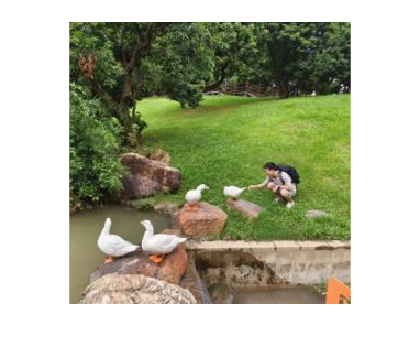

-----

checking picture number 20


Chi-squared distance (RGB) is: 0.632


SSIM score is: 0.449


Hue similarity is: 0.686


-----

close all;
debug = 1;
for i = 1:20
    fprintf("\n");
    target = imread("dataset/img_256/" + sprintf('%02d.jpg', i));
    imshow(target);
    
    % Histogram Comparison to check similarities
    %% Find similar pictures with the same colour etc.
    chi = ColorSim(source, target);

    % RGB2Grey -> Edge Detection -> SSIM index
    %% Find similar structures with same structure.
    sim = StructSim(source, target);

    % Histogram Comparison to check HSV similarities
    %% Find similar pictures with the same hue.
    hue_sim = HueSim(source, target);

    if (debug == 1)
        fprintf("-----");
        fprintf("checking picture number %02d\n", i);
        fprintf("Chi-squared distance (RGB) is: %.3f\n", chi);
        fprintf("SSIM score is: %.3f\n", sim);
        fprintf("Hue similarity is: %.3f\n", hue_sim(1));
        fprintf("-----");
    end

    if(chi < 0.3)
        if(chi < 0.1)
            fprintf("Same picture at %02d \n", i)
        else
            fprintf("Colour similarity in image %02d \n", i);
        end
    end

    if(sim < 0.3)
        fprintf("Colour similarity in image %02d \n", i);
    end

    fprintf("\n");

end

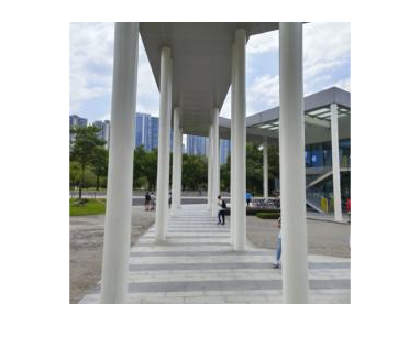

light = imread("dataset/img_256/16.jpg");
dark = imread("dataset/img_256/19.jpg");
imshow(light);

imshow(dark);

HueSim(light, dark)

ans =     0.2872    0.1554    0.4454


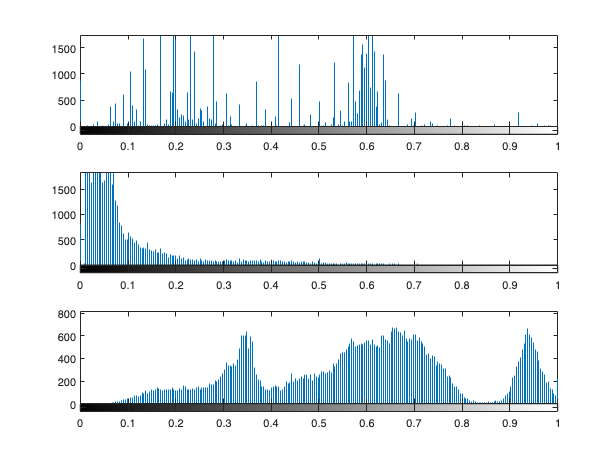

light_hsv = rgb2hsv(light);
dark_hsv = rgb2hsv(dark);
figure;
for i = 1:3
    subplot(3,1,i);
    imhist(light_hsv(:,:,i))
end

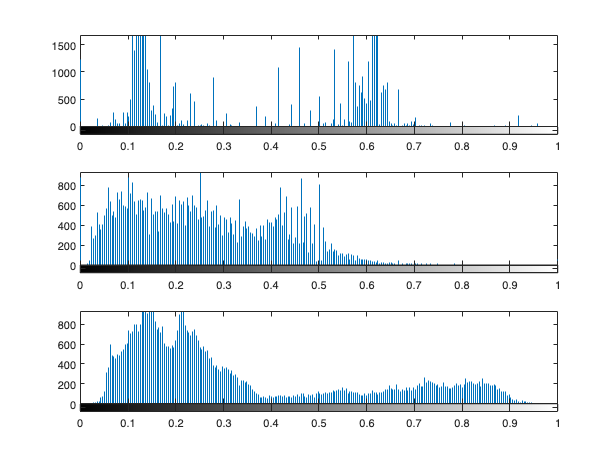


figure;
for i = 1:3
    subplot(3,1,i);
    imhist(dark_hsv(:,:,i))
end

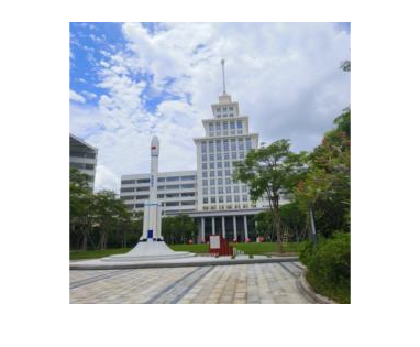


weird_pic = imread("dataset/img_256/14.jpg");
figure;
imshow(weird_pic);

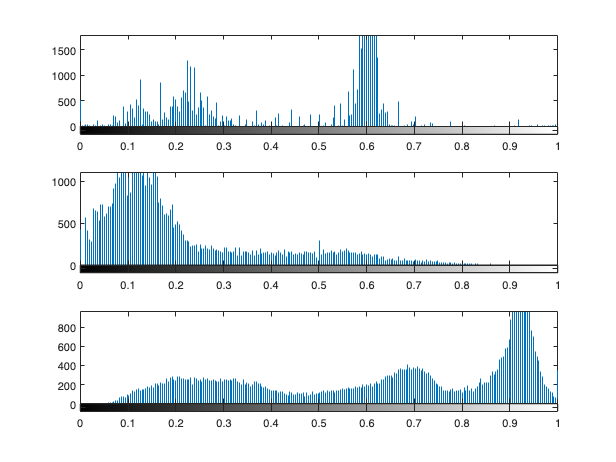

weird_pic = rgb2hsv(weird_pic);
figure;
for i = 1:3
    subplot(3,1,i);
    imhist(weird_pic(:,:,i))
end

HueSim(light_hsv, weird_pic)

ans =     0.1512    0.1190    0.3322


function score = ColorSim(I1, I2)
    score = 0;
    for i=1:3
        hist1 = imhist(I1(:,:,i));
        hist2 = imhist(I2(:,:,i));
        hist1 = hist1 / sum(hist1);
        hist2 = hist2 / sum(hist2);
        chiSquaredDistance = 0.5 * sum(((hist1 - hist2).^2) ./ (hist1 + hist2 + eps));
        score = score + chiSquaredDistance;
    end
end

function score = StructSim(I1, I2)
    grey1 = imgaussfilt(rgb2gray(I1), 1.5);
    grey2 = imgaussfilt(rgb2gray(I2), 1.5);
    grey1 = 255 * edge(grey1, "sobel");
    grey2 = 255 * edge(grey2, "sobel");
    score = ssim(grey1, grey2);
end

function scores = HueSim(I1, I2);
    I1 = rgb2hsv(I1);
    I2 = rgb2hsv(I2);
    
    hist1 = imhist(I1(:,:,1));
    hist2 = imhist(I2(:,:,1));
    hist1 = hist1 / sum(hist1);
    hist2 = hist2 / sum(hist2);
    
    chi_score = ChiCompare(hist1, hist2);
    eu_score = EuCompare(hist1, hist2);
    int_score = IntCompare(hist1, hist2);

    scores = [chi_score, eu_score, int_score];
end